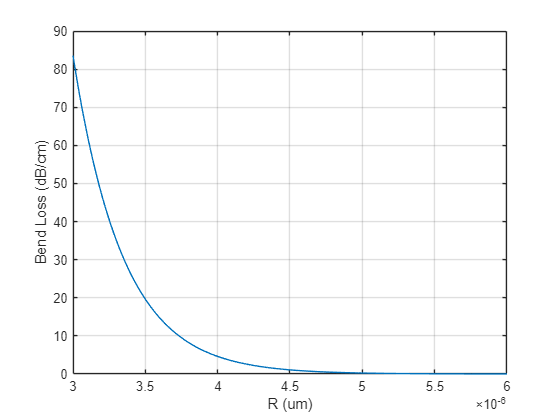

clear; clc; close all;

% Given parameters
lambda = 1.55e-6;   % um
a = 0.225e-6;       % um
n1 = 2.31;   
n0 = 1.46;
R = linspace(3e-6, 6e-6, 1000);  % um
k = 2*pi/lambda;   % Free space wavenumber
v = k*a*sqrt(n1^2 - n0^2);

%Solve numerically for b
dispersion = @(b) v*sqrt(1-b) - atan(sqrt(b./(1-b)));
b = fzero(dispersion, [0.001, 0.999]);

beta  = k * sqrt(n0^2 + b*(n1^2 - n0^2));   % propagation constant

kappa = sqrt(k^2 * n1^2 - beta^2);          % transverse wavenumber in core
sigma = sqrt(beta^2 - k^2 * n0^2);          % field decay constant in cladding

alpha = 0.5*sigma^2/(beta*(sigma*a+1)) * kappa^2/(k^2*(n1^2-n0*2)) * exp(2*sigma*a) * exp(-2*beta.*R.*atanh(sigma./beta) + 2.*R*sigma);

% Convert Np/m -> dB/cm
alpha_cm = alpha * 1e-2;
alpha_dB_cm = alpha_cm * 8.686;

figure;
plot(R, alpha_dB_cm);
xlabel('R (um)');
ylabel('Bend Loss (dB/cm)');
grid on;


fprintf('v-parameter = %.6f\n', v);

v-parameter = 1.632717


fprintf('b-parameter = %.6f\n', b);

b-parameter = 0.661532


fprintf('Parameter β = %.6e rad/m\n', beta);

Parameter β = 8.358306e+06 rad/m
